# GRUPPO G - identificazione  Giunto 2

- Fares Peter William Guirguis - mat.721654

- Mirandola Edoardo - mat. 723993

- Pennacchio Manuele - mat. 721965

# Inizializzazione del programma

clear all;
close all;
clc;
Group_name = 'GruppoG';
addpath("..\modelli\")
addpath("..\file_mat_init\")

# Inizializzazione del Sistema

model=ElasticRoboticSystem();
model.show;

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000



% visualizzazione output del sistema
output_number=model.getOutputNumber 

output_number = 4

for i=1:output_number
    fprintf('Output %d:    %s\n',i,model.getOutputName{i});
end

Output 1:    position_1
Output 2:    position_2
Output 3:    velocity_1
Output 4:    velocity_2



% visualizzazione sampling time
st=model.getSamplingPeriod;

# Risposta in frequenza del sistema

Il sistema in esame simula un robot SCARA. Ogni giunto può essere modellizzato come un sistema motore-trasmissione-carico con:

- trasmissione elastica

- attrito statico

Il metodo utilizzato per l'identificazione è il chirp in closed-loop, ossia l'applicazione di una successione di frequenze entro un intervallo predefinito

Considerando che l'attrito statico potrebbe generare problemi di identificazione a causa del continuo passaggio nei punti di velocità nulla, il segnale di eccitazione è composto da:

- **chirp**: segnale con frequenza variabile nel tempo entro intervalli predefiniti

- **portante**: segnale con frequenza costante utilizzato per diminuire l'effetto dell'attrito statico in fase di identificazione

## Controllore in cascata di base per l'identificazione in close-loop

% sistema + controllore
cs=ControlledSystemScara(model,Group_name);
% controllo del giunto 1
Kp_g1 = 100*360/(pi*2);%essendo 600 FSO per un grado per compensare metto 80N
Ki_g1 = Kp_g1/10;
% controllo del giunto 2
Kp_g2 = 0.01;
Ki_g2 = 0.1;
ctrl = ScaraBasicPIController(st, Kp_g1, Ki_g1, Kp_g2, Ki_g2);

% impostazione della coppia massima
ctrl.setUMax(model.getUMax);

% impostazione della isatanza del controllore
cs.setController(ctrl);

## Segnale di eccitazione

la durata del segnale dovrebbe essere al meno un periodo 

#### Portante

% parametri del segnale di eccitazione
omega_portante = 1;%[rad/s]
ampiezza_portante= 250;%[Nm]
T_portante=2*pi/omega_portante;
%vettore tempo (> T_portante)
t=(0:st:(1.1*T_portante))';

portante=ampiezza_portante*sin(omega_portante*t);

#### Chirp

ampliezza_identificazione= 250;%[Nm]
% frequenza minima
w0=omega_portante*10; %[rad/s]
% frequenza massima
w1=pi/st; %[rad/s]

chrip_id = ampliezza_identificazione*chirp(t,w0/2/pi,t(end),w1/2/pi,'logarithmic');

#### Azione di controllo = portante + chirp

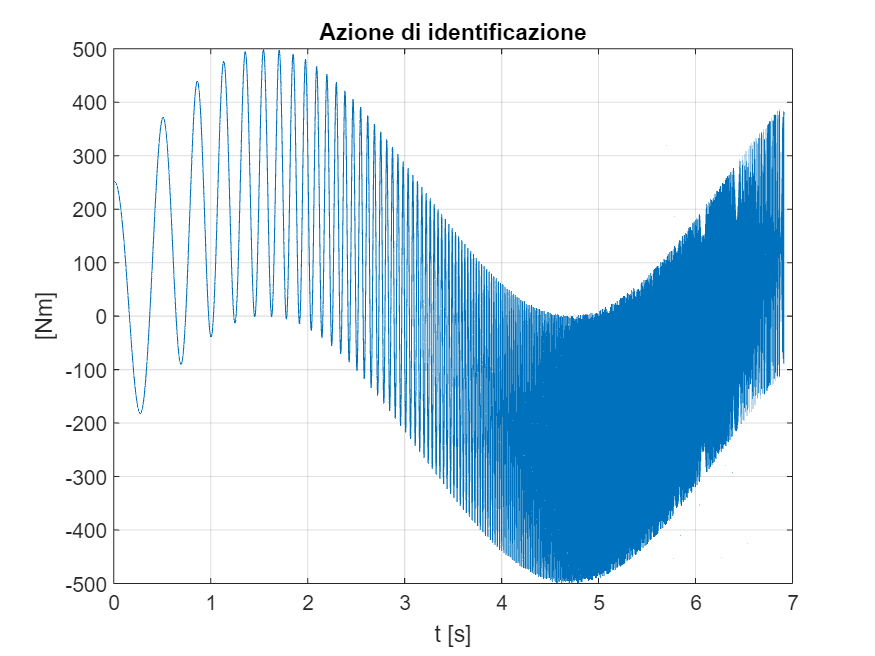

control_action = portante + chrip_id;

% grafico del segnale di eccitazione
figure();
plot(t,control_action)
xlabel('t [s]')
ylabel('[Nm]')
title('Azione di identificazione')
grid on

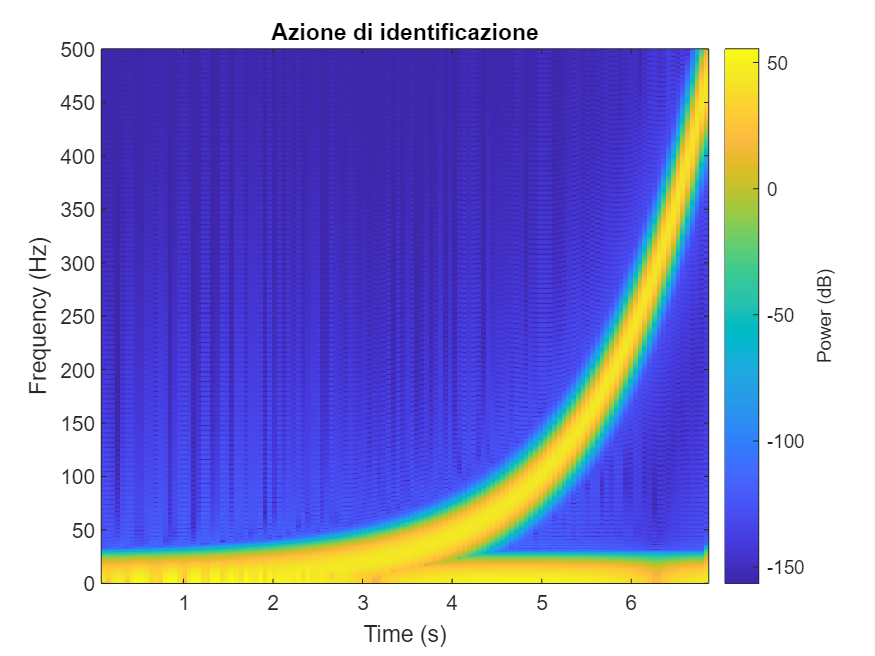

%spettrogramma del segnale di eccitazione
figure()
pspectrum(control_action,1/st,'spectrogram'); 
title('Azione di identificazione')


%riferimento
reference = zeros(length(t),model.getOutputNumber);

## Prova in anello chiuso

#### giunto 2

% creazione del segnale di eccitazione al giunto 2 e nullo per il giunto 1
exciting_signal_g2 = zeros(length(t),model.getInputNumber);
exciting_signal_g2(:,2) = control_action;
cs.initialize;
% applico il segnale di eccitazione al giunto 2
for idx=1:length(t)
    [process_output_g2(idx,:),control_action_g2(idx,:),t_g2(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g2(idx,:)');  
end

Grafici del'eccitazione e della risposta

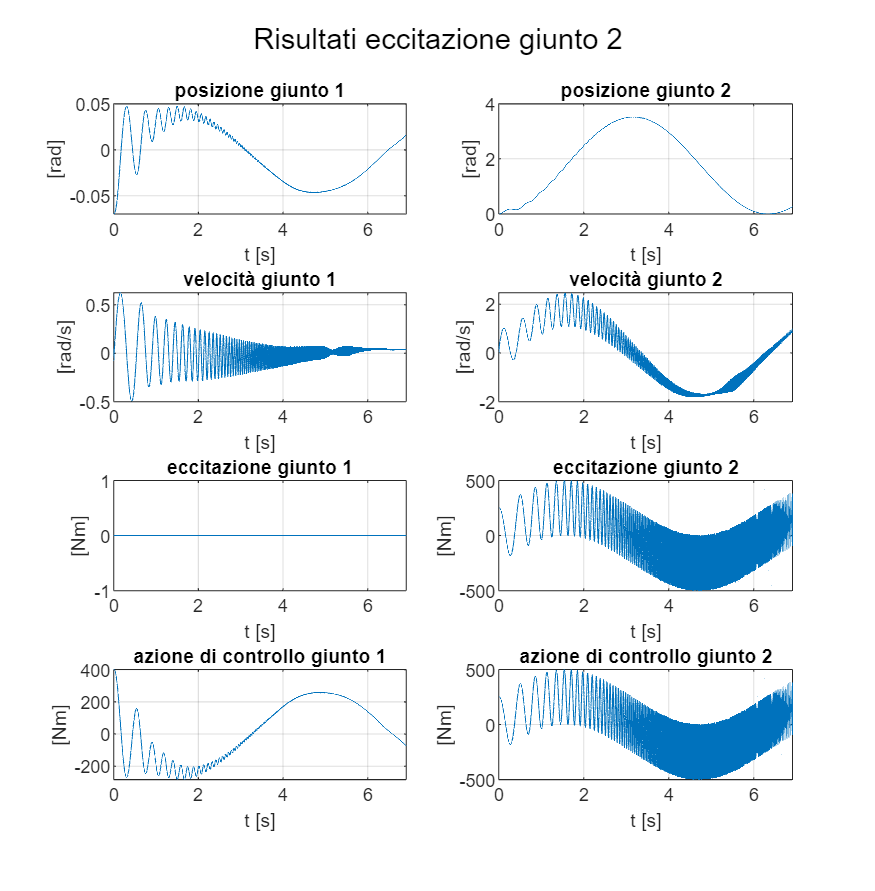

figure
subplot(4,2,1)
plot(t_g2,process_output_g2(:,1))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,3)
plot(t_g2,process_output_g2(:,3))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,5)
plot(t_g2,exciting_signal_g2(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,7)
plot(t_g2,control_action_g2(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di controllo giunto 1')
xlim([t(1) t(end)])
grid on

subplot(4,2,2)
plot(t_g2,process_output_g2(:,2))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 2')
xlim([t(1) t(end)])
grid on

subplot(4,2,4)
plot(t_g2,process_output_g2(:,4))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 2')
xlim([t(1) t(end)])
grid on

subplot(4,2,6)
plot(t_g2,exciting_signal_g2(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 2')
xlim([t(1) t(end)])
grid on

subplot(4,2,8)
plot(t_g2,control_action_g2(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di controllo giunto 2')
xlim([t(1) t(end)])
grid on

sgtitle('Risultati eccitazione giunto 2');
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -200 0 150])

## Risposta in frequenza

#### Giunto 2

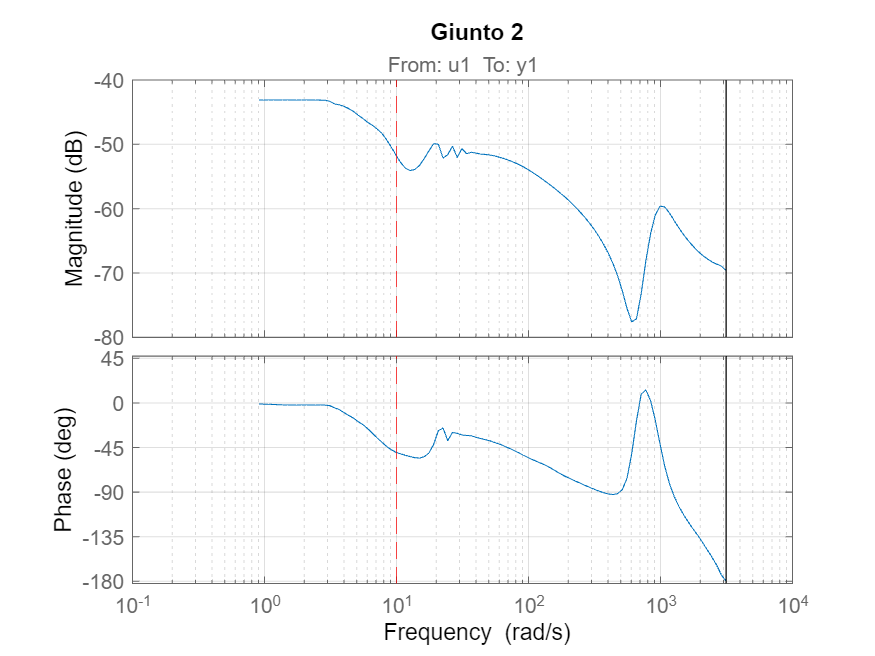

% modello giunto 2
identification_g2 = iddata(process_output_g2(:,4),control_action_g2(:,2),st);
frequency_response_identification_g2 = spafdr(identification_g2);
% diagramma di Bode giunto 2
figure();
subplot(1,1,1)
bode(frequency_response_identification_g2)
hold on
h1 = get(gcf,'Children');
xline(h1(2),w0,'--r')
xline(h1(3),w0,'--r')
hold off
grid on
title('Giunto 2');


pos = get(gcf, 'Position');

# Identificazione

il peso sulle frequenze consente la selezione delle frequenze più importanti per la stima del modello in quanto corrispondenti a quelle di lavoro

#### Modello del giunto 2 terzo ordine

range di frequenze di rilevanza tra 250 rad/s e 2000 rad/s

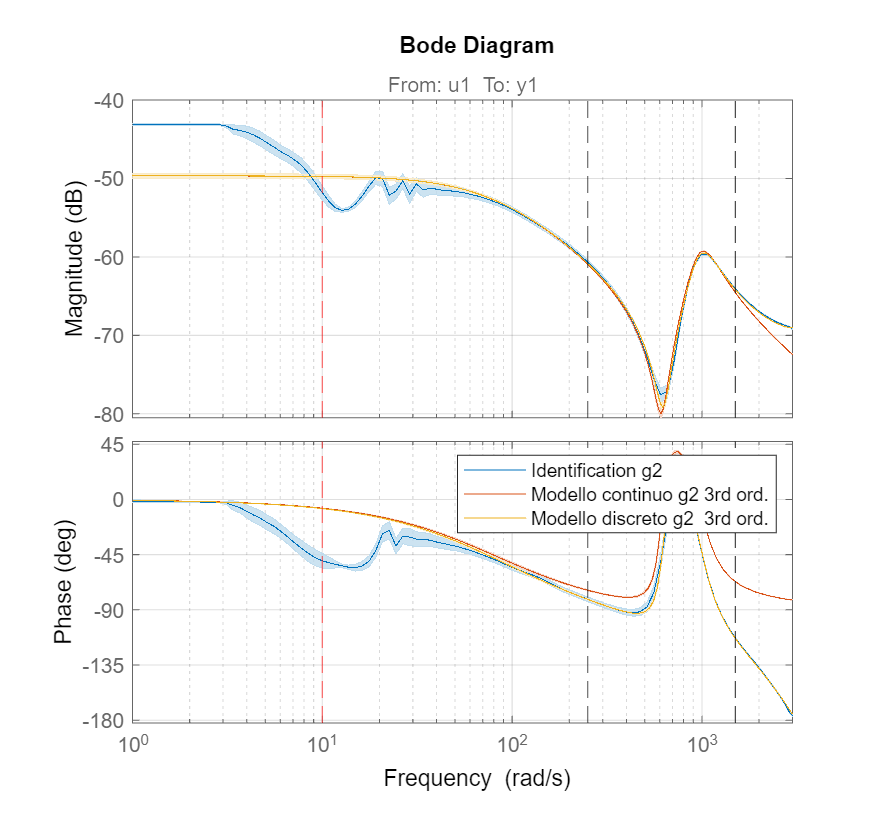

weight2_1 = 250;%rad/s
weight2_2 = 1500;%rad/s
peso = ones(length(frequency_response_identification_g2.Frequency),1);
% diminuzione del peso per per w<w1 e per w>w2
peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

% ottimizzazione della funzione di costo
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
% stima del modello come di ordine 5
modello_continuo_g2_3rd = ssest(frequency_response_identification_g2,3,opts);
modello_discreto_g2_3rd = ssest(frequency_response_identification_g2,3,'Ts',st,opts);

% diagramma di Bode del giunto 2
figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g2_3rd,modello_discreto_g2_3rd, bode_opts)

% plot linee di delimitazione delle frequenze di interesse
h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')
xline(h1(2),w0,'--r')
xline(h1(3),w0,'--r')

grid on
xlim([w0/10 weight2_2*2])

legend('Identification g2','Modello continuo g2 3rd ord.','Modello discreto g2  3rd ord.')
set(gcf, 'Position',pos+[0 -100 0 100])
hold off

#### Modello del giunto 2 quinto ordine

range di frequenze di rilevanza tra 250 rad/s e 2000 rad/s

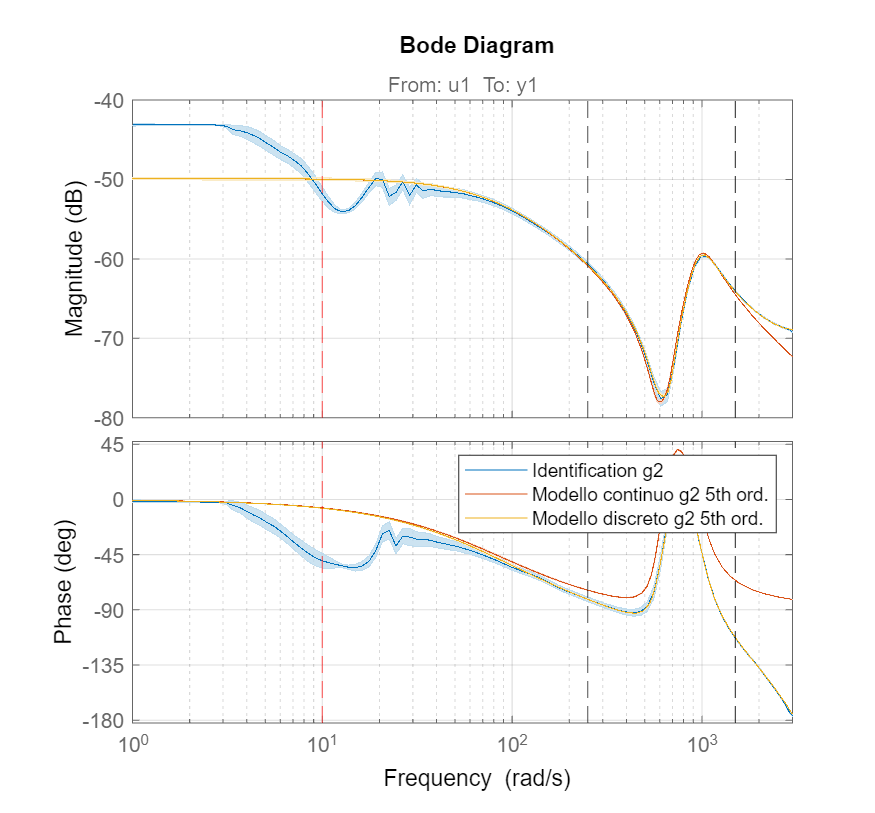

weight2_1 = 250;%rad/s
weight2_2 = 1500;%rad/s
peso = ones(length(frequency_response_identification_g2.Frequency),1);
% diminuzione del peso per per w<w1 e per w>w2
peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

% ottimizzazione della funzione di costo
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
% stima del modello come di ordine 5
modello_continuo_g2_5th = ssest(frequency_response_identification_g2,5,opts);
modello_discreto_g2_5th = ssest(frequency_response_identification_g2,5,'Ts',st,opts);

% diagramma di Bode del giunto 2
figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g2_5th,modello_discreto_g2_5th, bode_opts)

% plot linee di delimitazione delle frequenze di interesse
h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')
xline(h1(2),w0,'--r')
xline(h1(3),w0,'--r')

grid on
xlim([w0/10 weight2_2*2])

legend('Identification g2','Modello continuo g2 5th ord.','Modello discreto g2 5th ord.')
set(gcf, 'Position',pos+[0 -100 0 100])
hold off

#### Modello del giunto 2 settimo ordine

range di frequenze di rilevanza tra 250 rad/s e 2000 rad/s

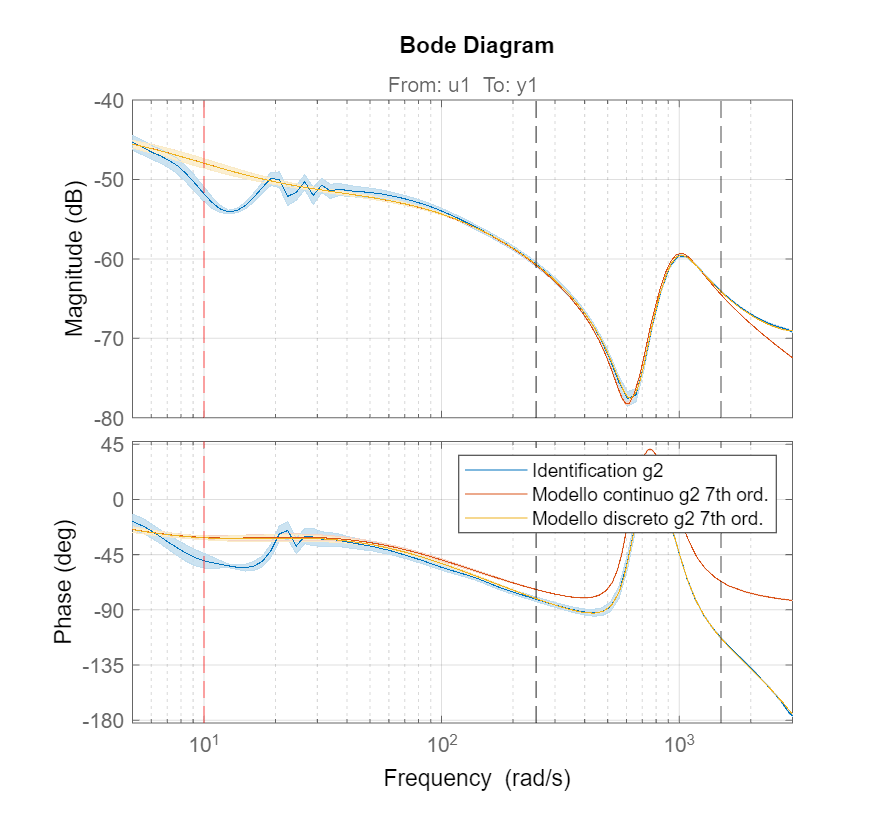

weight2_1 = 250;%rad/s
weight2_2 = 1500;%rad/s
peso = ones(length(frequency_response_identification_g2.Frequency),1);
% diminuzione del peso per per w<w1 e per w>w2
peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

% ottimizzazione della funzione di costo
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
% stima del modello come di ordine 5
modello_continuo_g2_7th = ssest(frequency_response_identification_g2,7,opts);
modello_discreto_g2_7th = ssest(frequency_response_identification_g2,7,'Ts',st,opts);

% diagramma di Bode del giunto 2
figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g2_7th,modello_discreto_g2_7th, bode_opts)

% plot linee di delimitazione delle frequenze di interesse
h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')
xline(h1(2),w0,'--r')
xline(h1(3),w0,'--r')
grid on
xlim([w0/2 weight2_2*2])

legend('Identification g2','Modello continuo g2 7th ord.','Modello discreto g2 7th ord.')
set(gcf, 'Position',pos+[0 -100 0 100])
hold off

## Modello del giunto 2 3rd Vs 5th Vs 7th

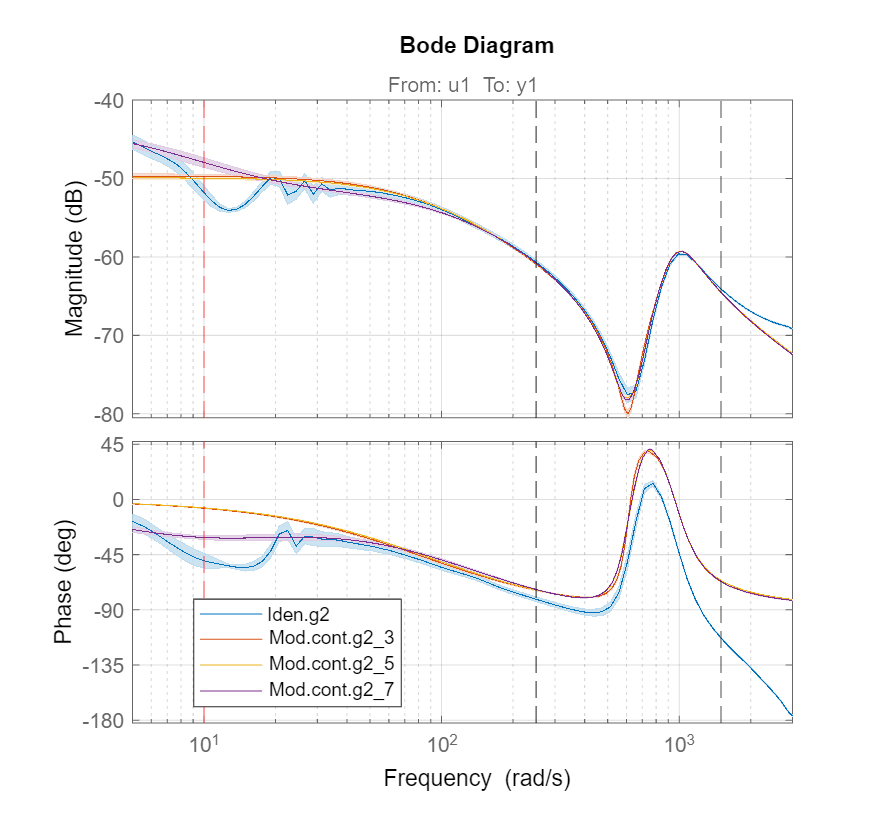

% diagramma di Bode del giunto 2
figure();
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g2_3rd,modello_continuo_g2_5th,modello_continuo_g2_7th, bode_opts)

% plot linee di delimitazione delle frequenze di interesse
h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')
xline(h1(2),w0,'--r')
xline(h1(3),w0,'--r')
grid on
xlim([w0/2 weight2_2*2])

legend('Iden.g2','Mod.cont.g2_3','Mod.cont.g2_5','Mod.cont.g2_7','Location','best')
set(gcf, 'Position',pos+[0 -100 0 100])
hold off

# SI E' SCELTO IL MODELLO DEL 5° ORDINE - essendo che il  7° non introduce miglioramenti e il 3° si discosta maggiormente rispetto che al 5° nelle frequenza di interesse  

# Validazione

Per la fase di validazione, è stato scelto un segnale composto da una chirp e una portante, utilizzando parametri diversi rispetto al caso precedente. Combinando la chirp e la portante nel segnale composto, è possibile stimolare il sistema e verificare la sua risposta in condizioni diverse da quelle utilizzate per l'identificazine.

Si noti che durante la fase di validazione la portante prende la forma di un coseno e che il segnale di chirp assume una distribuzione quadratica in frequenza

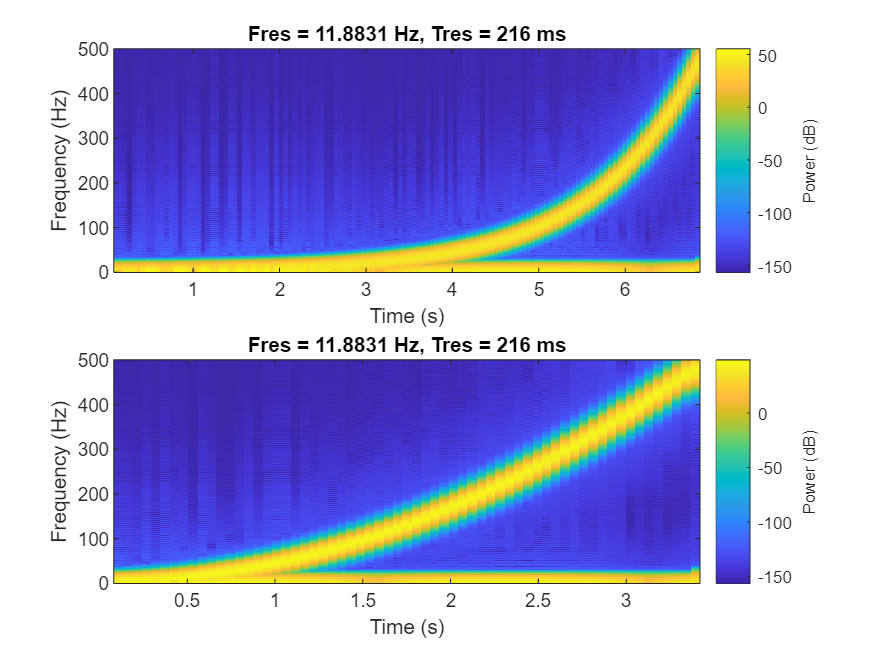

% parametri di validazione
ampliezza_validazione = 250;%[Nm]
omega_portante_validation = 2;%[rad/s]
ampiezza_portante_validation = 130;%[Nm]

% portante di validazione
T_portante_val=2*pi/omega_portante_validation;  %[s]
t_val=(0:st:(1.1*T_portante_val))';
portante_v=ampiezza_portante_validation*sin(omega_portante_validation*t_val);
% chirp di validazione
w0_v=omega_portante_validation*10; %[rad/s]
w1_v=pi/st; %[rad/s]
chrip_val = chirp(t_val,w0_v/2/pi,t_val(end),w1_v/2/pi, 'quadratic')*ampliezza_validazione;
% eccitazione di validazione
control_action_validation = portante_v + chrip_val;

% plot delle azioni di identificazione e di validazione
figure();
% spettrogramma dell'azione di identificazione
subplot(2,1,1)
title("Identificazione")
pspectrum(control_action,1/st,'spectrogram');
% spettrogramma dell'azione di validazione
subplot(2,1,2)
title("Validazione")
pspectrum(control_action_validation,1/st,'spectrogram');

#### Validazione del giunto 2

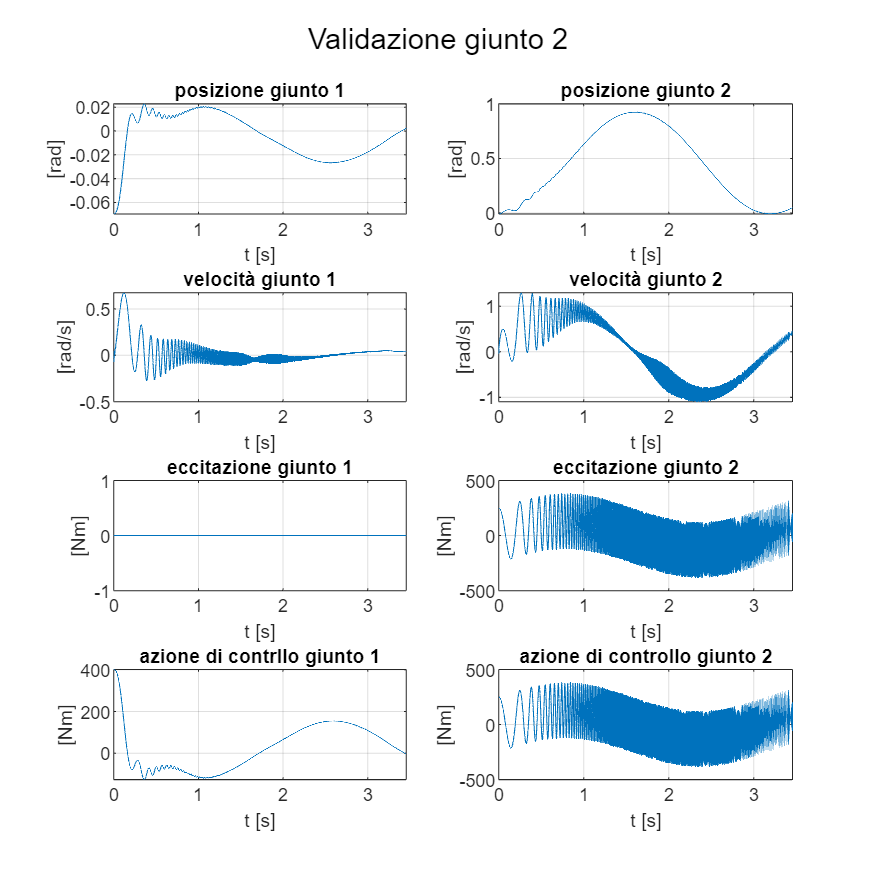

exciting_signal_g2_validation = zeros(length(t_val),model.getInputNumber);
exciting_signal_g2_validation(:,2) = control_action_validation;

cs.initialize 
for idx=1:length(t_val)
    [process_output_g2_validation(idx,:),control_action_g2_validation(idx,:),t_g2_validation(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g2_validation(idx,:)');  
end

validation_g2 = iddata(process_output_g2_validation(:,4),control_action_g2_validation(:,2),st);
frequency_response_validazione_g2 = spafdr(validation_g2);

figure();
subplot(4,2,1)
plot(t_g2_validation,process_output_g2_validation(:,1))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,3)
plot(t_g2_validation,process_output_g2_validation(:,3))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,5)
plot(t_g2_validation,exciting_signal_g2_validation(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,7)
plot(t_g2_validation,control_action_g2_validation(:,1))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di contrllo giunto 1')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,2)
plot(t_g2_validation,process_output_g2_validation(:,2))
xlabel('t [s]')
ylabel('[rad]')
title('posizione giunto 2')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,4)
plot(t_g2_validation,process_output_g2_validation(:,4))
xlabel('t [s]')
ylabel('[rad/s]')
title('velocità giunto 2')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,6)
plot(t_g2_validation,exciting_signal_g2_validation(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('eccitazione giunto 2')
xlim([t_val(1) t_val(end)])
grid on

subplot(4,2,8)
plot(t_g2_validation,control_action_g2_validation(:,2))
xlabel('t [s]')
ylabel('[Nm]')
title('azione di controllo giunto 2')
xlim([t_val(1) t_val(end)])
grid on

sgtitle('Validazione giunto 2');
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -200 0 150])

#### Diagramma di bode della risposta in frequenza

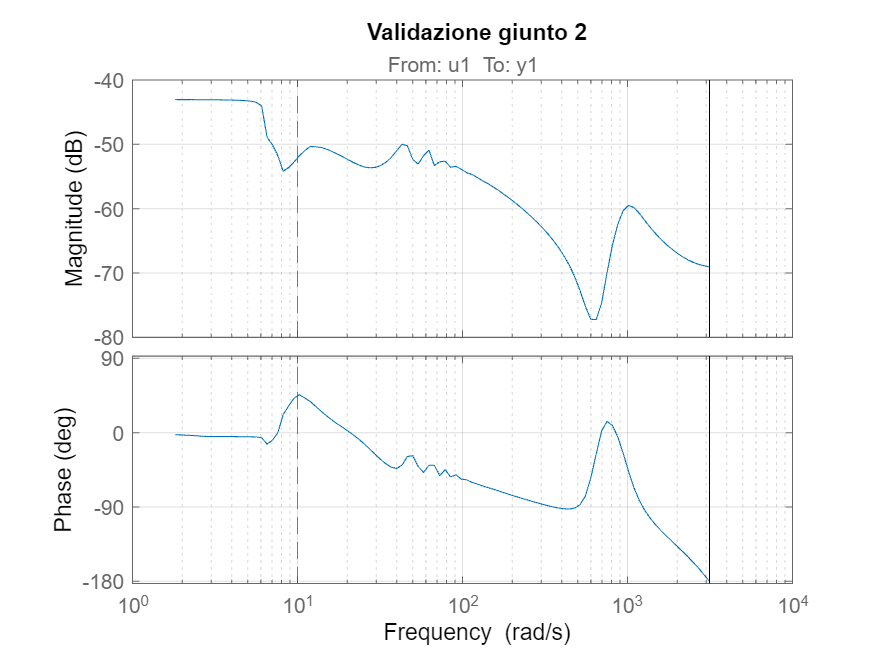

figure();
subplot(1,1,1)
bode(frequency_response_validazione_g2)
title('Validazione giunto 2')
hold on
h1 = get(gcf,'Children');
xline(h1(2),w0,'--r')
xline(h1(3),w0,'--r')
hold off
grid on

## Validazione

#### Giunto 2

    Confronto tra validazione e modello discreto e continuo

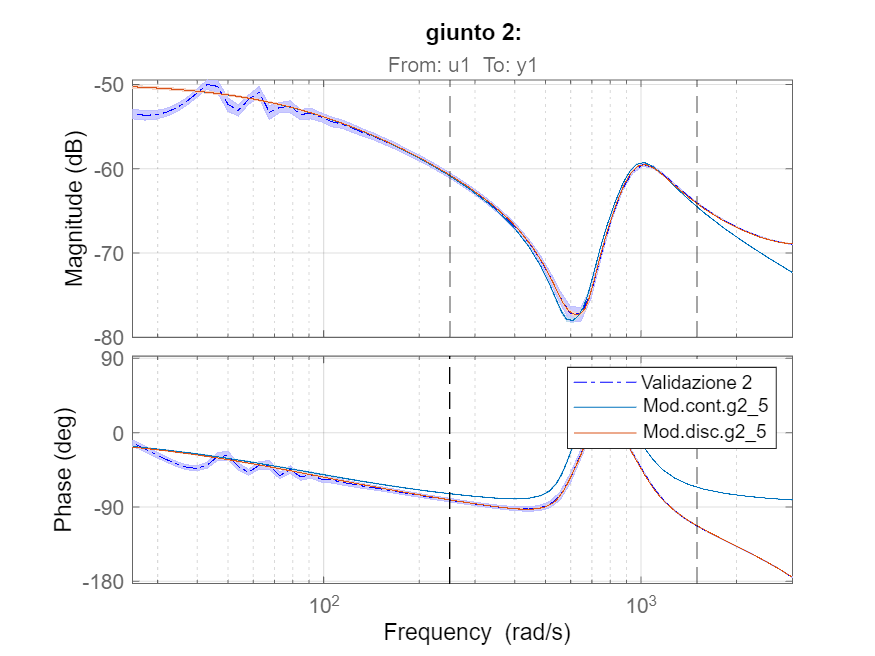

figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g2,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_continuo_g2_5th, bode_opts)
bode(modello_discreto_g2_5th, bode_opts)
plot([weight2_1 weight2_1],ylim,'--k')
h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')
grid on
xlim([weight2_1/10 weight2_2*2])

legend('Validazione 2','Mod.cont.g2_5','Mod.disc.g2_5')
title('giunto 2: ')
hold off

Risposta in frequenza della validazione e identificazione

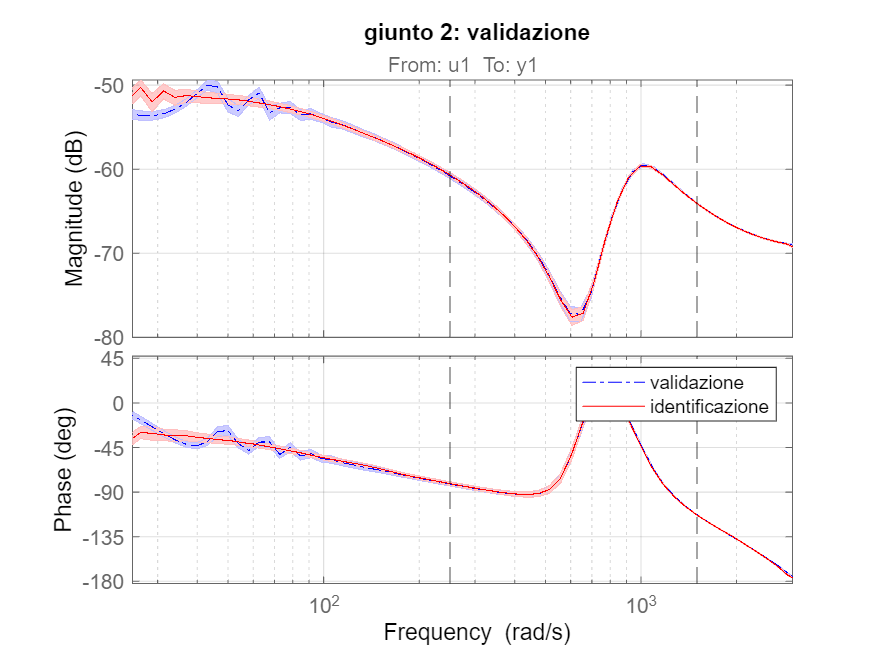

figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

h=bodeplot(frequency_response_validazione_g2,'b-.', bode_opts);
hold on

showConfidence(h,3)
bode(frequency_response_identification_g2, bode_opts,'r')

h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')

hold off
grid on
xlim([weight2_1/10 weight2_2*2])
title('giunto 2: validazione')
legend('validazione','identificazione')

Identificazione Vs validazione

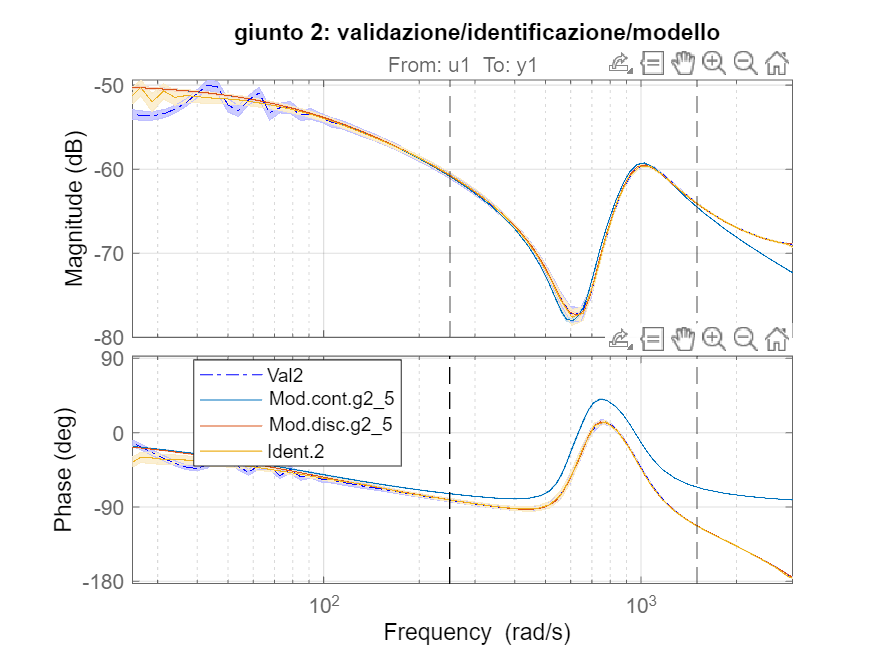

figure()
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g2,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_continuo_g2_5th, bode_opts)
bode(modello_discreto_g2_5th, bode_opts)
bode(frequency_response_identification_g2)
plot([weight2_1 weight2_1],ylim,'--k')
h1 = get(gcf,'Children');
xline(h1(3),weight2_1,'--k')
xline(h1(3),weight2_2,'--k')
xline(h1(2),weight2_1,'--k')
xline(h1(2),weight2_2,'--k')
grid on
xlim([weight2_1/10 weight2_2*2])

legend('Val2','Mod.cont.g2_5','Mod.disc.g2_5', 'Ident.2','Location','best')
title('giunto 2: validazione/identificazione/modello')
hold off


save("..\file_mat_init\ide_giunto2.mat","modello_continuo_g2_5th")
